# Analyze magnetization data taken in the MPMS

## Temperature sweep at zero field

SampleName = 'TmAsO4-LS5341-MS180511';
FileName = strcat(SampleName,'_MvsT_20180511.dat');
Data = ImportMagnetization(FileName);
ttl_temp = sprintf('Temperature dependence of the magnetization of %s\n', SampleName);
ttl_inv = sprintf('Temperature dependence of the inverse magnetization of %s\n', SampleName);

T = Data.TemperatureK;
H = Data.MagneticFieldOe;
M = Data.Momentemu;

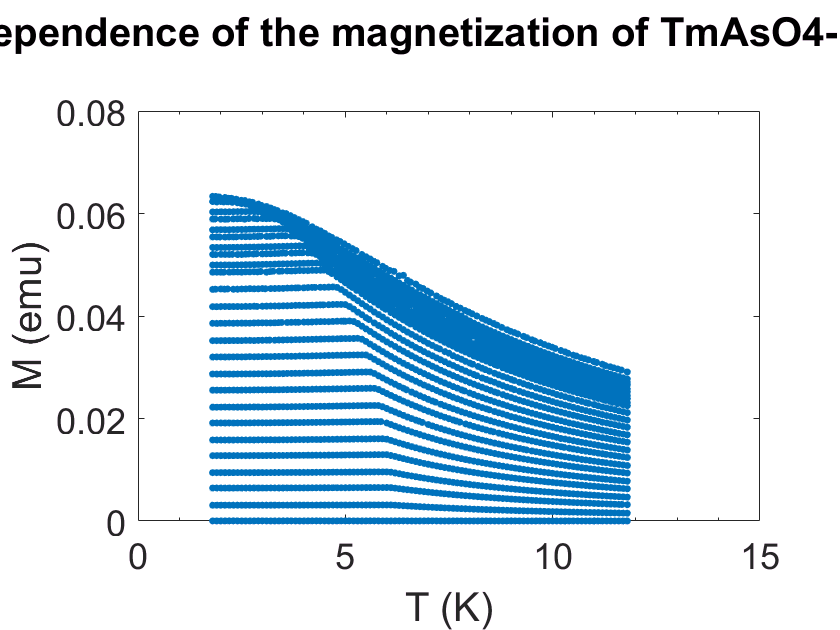

InvM = H./M;
%figure
plot(T,M,'.')
xlabel('T (K)')
ylabel('M (emu)')
title(ttl_temp);

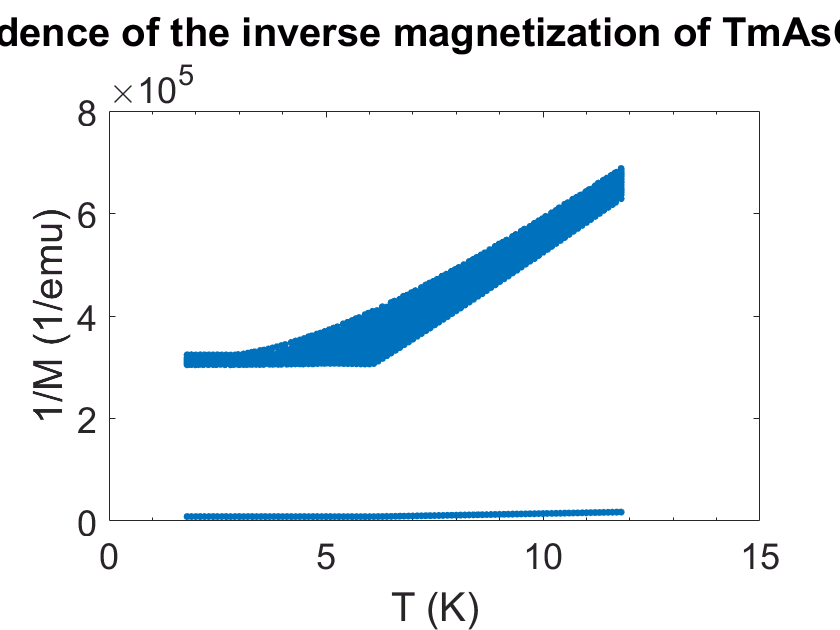

figure
plot(T,InvM,'.')
xlabel('T (K)')
ylabel('1/M (1/emu)')
title(ttl_inv);

## Field sweeps at constant temperature

% FieldData = ImportTmVO4Magnetization('2018-03-05_PM_TmVO4-LS5228-MP3-Plt_Field-sweeps.dat');

% Tfd = FieldData.TemperatureK;
% Hfd = FieldData.MagneticFieldOe;
% Mfd = FieldData.Momentemu;

% plot(Hfd,Mfd,'.')
% xlabel('H (Oe)')
% ylabel('M (emu)')
% title('Field dependence of the magnetization of TmVO4-LS5228-MP3');

% clear separatedMHData
% 
% temps = linspace(1.8,2.2,5);
% isTemp = true(1,length(temps));
% 
% for i = 1:length(temps)
%     wp = abs(Tfd-temps(i))<0.05;
%     separatedMHData(i).H = Hfd(wp);
%     separatedMHData(i).T = Tfd(wp);
%     separatedMHData(i).M = Mfd(wp);
%     if length(Tfd(wp))<1
%         isTemp(i) = 0;
%     end
%     
%     [separatedMHData(i).H,wo] = sort(separatedMHData(i).H);
%     separatedMHData(i).T = separatedMHData(i).T(wo);
%     separatedMHData(i).M = separatedMHData(i).M(wo);
% end

% figure
% for i=1:length(temps)
%     plot(separatedMHData(i).H,separatedMHData(i).M,'-+')
%     hold on
% end
% xlabel('Magnetic field (Oe)')
% ylabel('M (emu)')
% legendCell = cellstr(num2str(temps(isTemp)', '%.1f K'));
% legend(legendCell,'Location','northwest')
% title('Field dependence of the magnetization of TmVO4-LS5228-MP3')
% hold off

## Temperature sweeps at constant field

TempData = ImportTmVO4Magnetization(FileName);

Ttd = TempData.TemperatureK;
Htd = TempData.MagneticFieldOe;
Mtd = TempData.Momentemu;

clear separatedMHData

fields = [linspace(0,20000,11), linspace(11000,19000,5), linspace(14500,19500,6)];
isField = true(1,length(fields));

for i = 1:length(fields)
    wp = abs(Htd-fields(i))<50;
    separatedMTData(i).H = Htd(wp);
    separatedMTData(i).T = Ttd(wp);
    separatedMTData(i).M = Mtd(wp);
    if length(Htd(wp))<1
        isField(i) = 0;
    end
    
    [separatedMTData(i).H,wo] = sort(separatedMTData(i).H);
    separatedMTData(i).T = separatedMTData(i).T(wo);
    separatedMTData(i).M = separatedMTData(i).M(wo);
end

## Magnetization at different fields

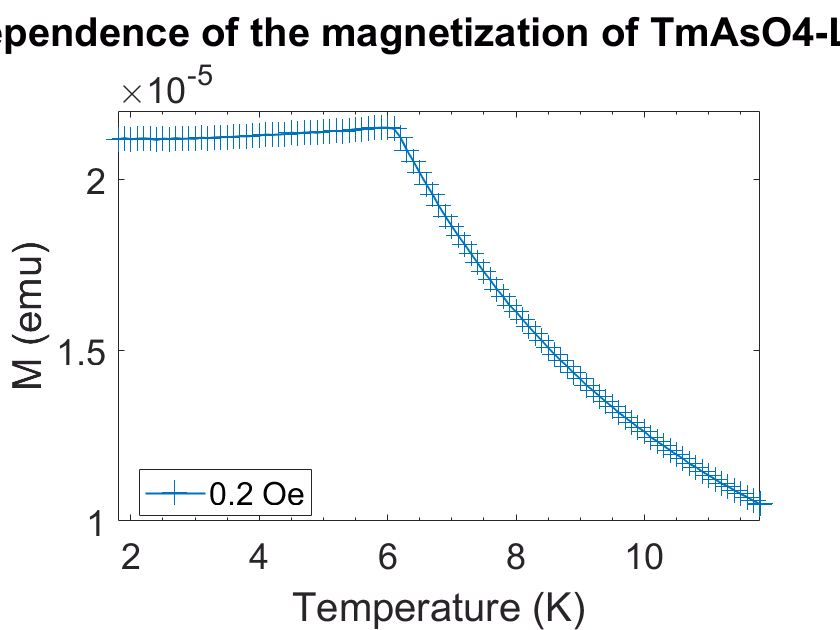

set(0,'defaultAxesXLimSpec', 'tight')
set(0,'defaultAxesXMinorTick', 'on')

figure
plot(separatedMTData(1).T,separatedMTData(1).M,'-+')
xlabel('Temperature (K)')
ylabel('M (emu)')
legend({sprintf('%.1f Oe', separatedMTData(1).H(1))},'Location','best')
title(ttl_temp)

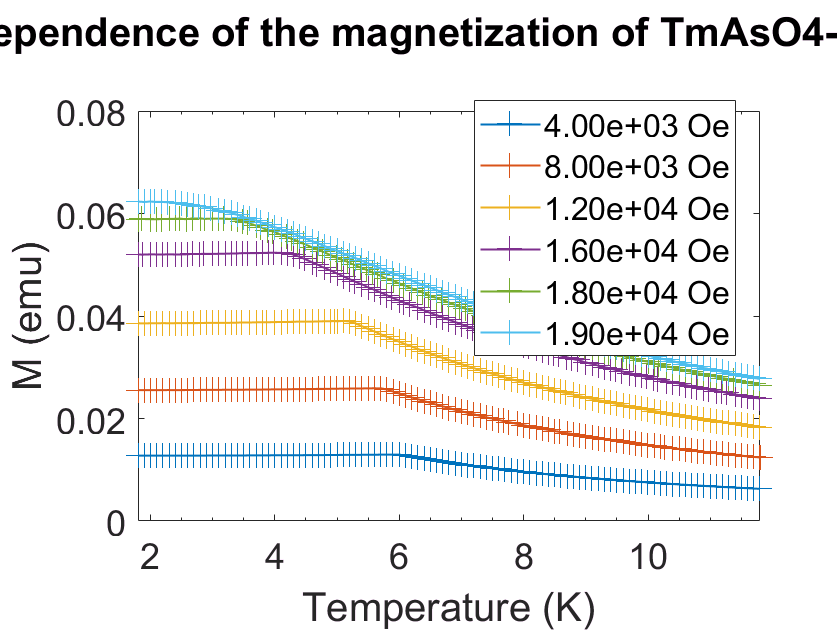


numlgd=[4000,8000,12000,16000,18000,19000];
figure
for i=2:length(fields)
    if ismember(fields(i),numlgd)
    plot(separatedMTData(i).T,separatedMTData(i).M,'-+')
    hold on
    end
end
xlabel('Temperature (K)')
ylabel('M (emu)')
legendCell = cellstr(num2str(numlgd', '%.1e Oe'));
legend(legendCell,'Location','best')
title(ttl_temp)
hold off

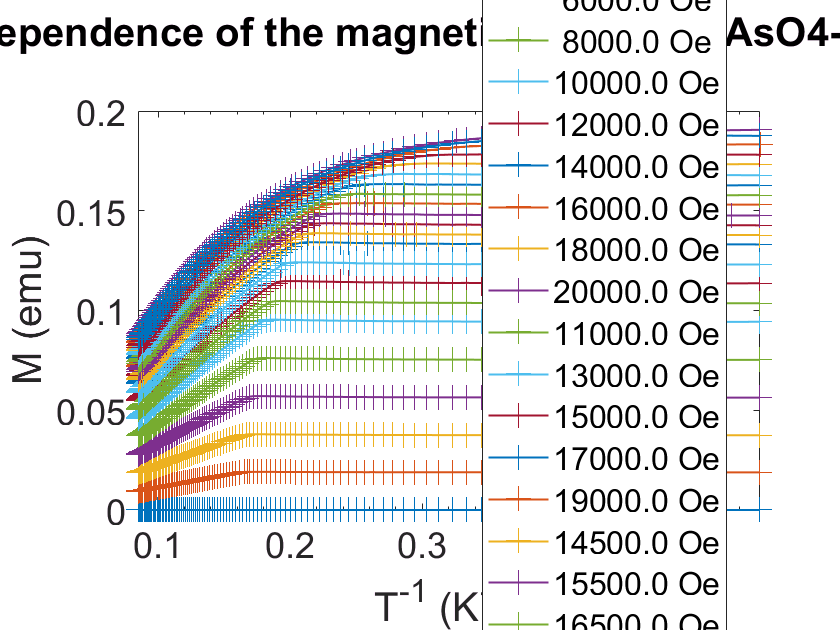

figure
for i=1:length(fields)
    plot(1./separatedMTData(i).T,separatedMTData(i).M,'-+')
    hold on
end
xlabel('T^{-1} (K^{-1})')
ylabel('M (emu)')
legendCell = cellstr(num2str(fields(isField)', '%.1f Oe'));
legend(legendCell,'Location','best')
title(ttl_temp)
hold off


figure
% plot(separatedMTData(1).T,1./separatedMTData(1).M*separatedMTData(1).M(separatedMTData(1).T==min(separatedMTData(1).T))...
%     /separatedMTData(2).M(separatedMTData(2).T==min(separatedMTData(2).T))*fields(2) -1,'-+')
plot(separatedMTData(1).T,1./separatedMTData(1).M,'-+')
hold on
for i=2:length(fields)
    if ismember(fields(i),numlgd)
        plot(separatedMTData(i).T,1./separatedMTData(i).M*fields(i)-1+fields(i)/1000,'-+')
    end
end

numlgd =            0        4000        8000       12000       16000       18000       19000


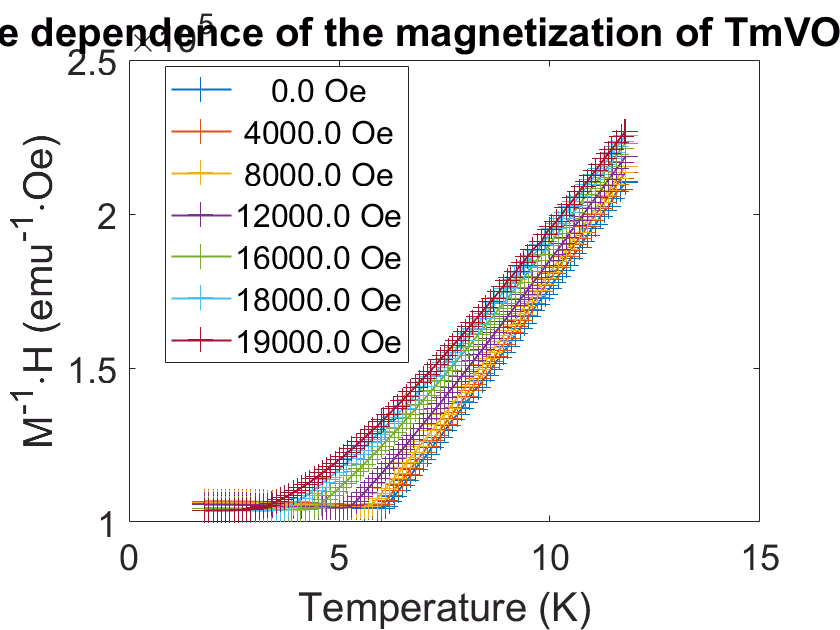

xlabel('Temperature (K)')
ylabel('M^{-1}\cdot{}H (emu^{-1}\cdot{}Oe)')
% legendCell = cellstr(num2str(numlgd', '%.1f Oe'));
legend(legendCell,'Location','best')
title(ttl_temp)
hold off

T = [separatedMTData(1:11).T];%Converting structure elements into arrays. Note well: all the cells of the
M = [separatedMTData(1:11).M];%structure element which are to be converted must contain matrices with the same
H = [separatedMTData(1:11).H];% dimensions. This is why the range 1:11 was chosen: the matrices in cells 12 and 13
% have different dimensions.
InvM = 1./M;